# Applying Ocean Color Algorithms

Description: This script loops through a directory with Landsat 8 images and applies the Quasi-Analytical Algorithm (version 6) from Lee et al. 2002, diffuse attenuation coefficient algorithm from Lee et al. 2004, Landsat 8 Secchi disk depth algorithm from Lee et al. 2016, and SAVE model from Wei et al. (2018). 

% Set Up
clear
clc
close all 

% Change to virginiaCoast Folder
cd '/Volumes/harddrive/virginiaCoast/' % Change for your system

% Add Functions to Path 
addpath('/Volumes/harddrive/virginiaCoast/functions/l8functions') % Change for your system

% Loop Through Directory and Write Coordinates to a Structure
sdir = dir('/Volumes/harddrive/virginiaCoast/datasets/l8/*OC');
spath = '/Volumes/harddrive/virginiaCoast/datasets/l8';

% Specify Variables and Coordinates of Interest
vi = {'Lat','Lon','kd_490','chl','rrs_443','rrs_482','rrs_561','rrs_655','l2_flags'};

%Change site names and add appropriate coordinates
site_names = {'Site 6','Site 12', 'Site 17'};
coord = [37.36764 -75.73592; 37.4670924 -75.668335; 37.29038 -75.784927];

% Specify Wavelength
wl = [443 482 561 655];

% Loop Through Images
for file = 1:length(sdir)
    
    cd(spath)
    
    % Read Files
    filename = sdir(file).name;
    L8_raw = readL2(filename);
    
    % Write Datetime Information to Structure
    L8coord.date(file) = L8_raw.date;
    
    % Write Variables of Interest 
    for param = 1:length(vi)
        L8coord.(vi{param})(:,:,file) = extractC(L8_raw.(vi{param}), L8_raw.Lat, L8_raw.Lon, coord);
    end
    
end

## Apply Quasi Analytical Algorithm (v6) to Derive Inherent Optical Properties

for image = 1:size(L8coord.rrs_443,3)
    for site = 1:size(L8coord.rrs_443,2)
        for meas = 1:size(L8coord.rrs_443,1)
        
        % Set Rrs Values
        Rrs = [L8coord.rrs_443(meas,site,image) L8coord.rrs_482(meas,site,image) L8coord.rrs_561(meas,site,image) L8coord.rrs_655(meas,site,image)];
        Rrs(Rrs<0)=nan
        % Apply QAA
        [a(meas,:,site,image), bb(meas,:,site,image), apg(meas,:,site,image), bbp(meas,:,site,image), id_ref(meas,:,site,image)] = qaa_v6_l8(Rrs, wl);
        end
    end
end

Rrs =     0.0086    0.0122    0.0170    0.0094


Rrs =     0.0096    0.0132    0.0172    0.0095


Rrs =     0.0088    0.0125    0.0168    0.0092


Rrs =     0.0069    0.0106    0.0163    0.0098


Rrs =     0.0079    0.0117    0.0168    0.0095


Rrs =     0.0091    0.0126    0.0169    0.0093


Rrs =     0.0090    0.0126    0.0175    0.0103


Rrs =     0.0082    0.0121    0.0170    0.0099


Rrs =     0.0078    0.0118    0.0166    0.0095


Rrs =     0.0093    0.0127    0.0174    0.0100


Rrs =     0.0089    0.0124    0.0171    0.0100


Rrs =     0.0091    0.0124    0.0172    0.0101


Rrs =     0.0093    0.0127    0.0174    0.0102


Rrs =     0.0091    0.0127    0.0173    0.0104


Rrs =     0.0089    0.0124    0.0173    0.0104


Rrs =     0.0087    0.0122    0.0170    0.0104


Rrs =     0.0086    0.0123    0.0170    0.0103


Rrs =     0.0086    0.0124    0.0171    0.0105


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =    NaN   NaN   NaN   NaN


Rrs =     0.0047    0.0084    0.0144    0.0095


Rrs =     0.0051    0.0089    0.0148    0.0099


Rrs =     0.0050    0.0088    0.0146    0.0099


Rrs =     0.0046    0.0082    0.0140    0.0096


Rrs =     0.0050    0.0086    0.0146    0.0099


Rrs =     0.0049    0.0088    0.0144    0.0100


Rrs =     0.0045    0.0079    0.0138    0.0093


Rrs =     0.0046    0.0084    0.0141    0.0097


Rrs =     0.0042    0.0079    0.0141    0.0098


Rrs =     0.0081    0.0117    0.0168    0.0108


Rrs =     0.0084    0.0118    0.0170    0.0108


Rrs =     0.0082    0.0117    0.0165    0.0110


Rrs =     0.0070    0.0110    0.0161    0.0103


Rrs =     0.0086    0.0121    0.0172    0.0109


Rrs = 1×4
    0.0084    0.0120    0.0170    0.0114


Rrs = 1×4
    0.0073    0.0109    0.0160    0.0104


Rrs = 1×4
    0.0091    0.0123    0.0174    0.0113


Rrs = 1×4
    0.0078    0.0114    0.0167    0.0106


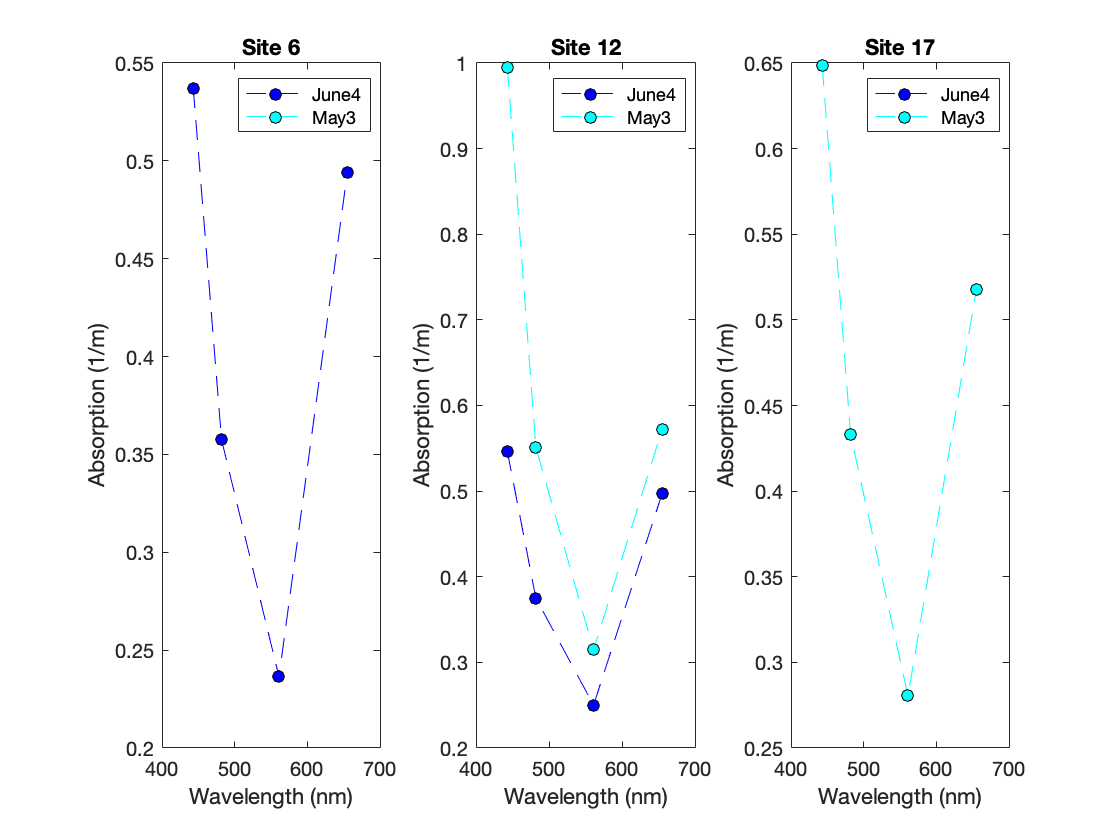


% Quick Visualization for Absorption
a_demo = squeeze(nanmean(a,1));
%Change "3" to the amount of satellite images you are using.
colors = jet(size(a_demo,2));

% Plot Absorption Spectra
figure(1)
for pl = 1:size(a_demo,2)
    %Change "3" to the amount of sites you are trying to plot. Be sure to
    %modify this for every occurrence of thie line.
    subplot(1,3,pl)
    for image = 1:size(a_demo,3)
        plot(wl, a_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Absorption (1/m)')
        hold on
    end
    %Update for the number of images you have and repeat for every
    %occurrence of this line.
    legend({'June4', 'May3'})
    title(site_names{pl})
end

## Applying iop2kd function for derive Kd from IOPs

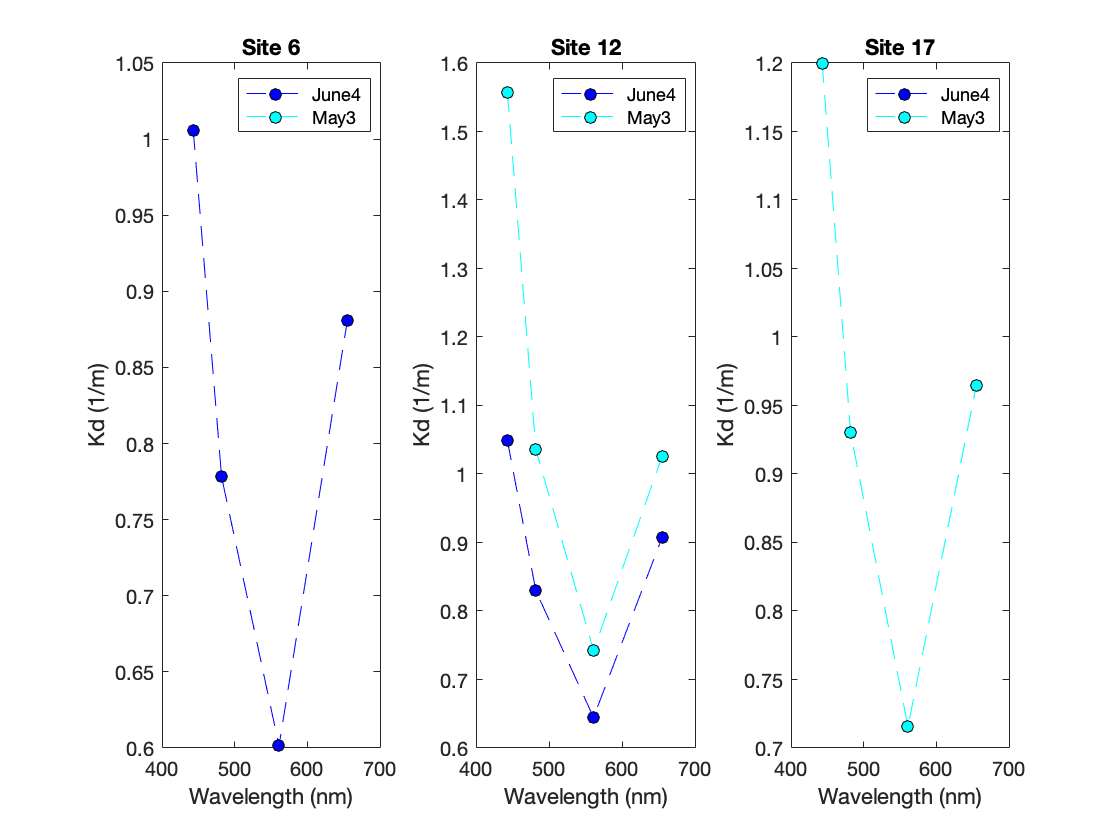

% Specify Inputs
bbw = [0.002 0.0014 0.0008 0.004];
sa = 30;

% Loop Through Matrices
for image = 1:size(a,4)
    for site = 1:size(a,3)
        for meas = 1:size(a,1)
            kd(meas,:,site,image) =iop2kd(a(meas,:,site,image),bb(meas,:,site,image),bbw,sa);
        end
    end
end 

% Quick Visualization
kd_demo = squeeze(nanmean(kd,1));

figure(2)
for pl = 1:size(kd_demo,2)
    subplot(1,3,pl)
    for image = 1:size(kd_demo,3)
        plot(wl, kd_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Kd (1/m)')
        hold on
    end
    legend({'June4', 'May3'})
    title(site_names{pl})
end

## Applying Lee et al. (2016) Secchi Algorithm

for image = 1:size(L8coord.rrs_443,3)
    for site = 1:size(L8coord.rrs_443,2)
        for meas = 1:size(L8coord.rrs_443,1)
        
        % Set Rrs Values
        Rrs = [L8coord.rrs_443(meas,site,image) L8coord.rrs_482(meas,site,image) L8coord.rrs_561(meas,site,image) L8coord.rrs_655(meas,site,image)];
        Rrs(Rrs<0)=nan
        % Set Kd Values
        Kd = kd(meas,:,site,image);
        
        % Apply secchi_L8 funtion
        [Kdminwl(meas,site,image), Secchi(meas,site,image), Kdmin(meas,site,image)] = secchi_L8(Rrs, Kd, wl);
        
        end
    end
end

Rrs = 1×4
    0.0086    0.0122    0.0170    0.0094


Rrs = 1×4
    0.0096    0.0132    0.0172    0.0095


Rrs = 1×4
    0.0088    0.0125    0.0168    0.0092


Rrs = 1×4
    0.0069    0.0106    0.0163    0.0098


Rrs = 1×4
    0.0079    0.0117    0.0168    0.0095


Rrs = 1×4
    0.0091    0.0126    0.0169    0.0093


Rrs = 1×4
    0.0090    0.0126    0.0175    0.0103


Rrs = 1×4
    0.0082    0.0121    0.0170    0.0099


Rrs = 1×4
    0.0078    0.0118    0.0166    0.0095


Rrs = 1×4
    0.0093    0.0127    0.0174    0.0100


Rrs = 1×4
    0.0089    0.0124    0.0171    0.0100


Rrs = 1×4
    0.0091    0.0124    0.0172    0.0101


Rrs = 1×4
    0.0093    0.0127    0.0174    0.0102


Rrs = 1×4
    0.0091    0.0127    0.0173    0.0104


Rrs = 1×4
    0.0089    0.0124    0.0173    0.0104


Rrs = 1×4
    0.0087    0.0122    0.0170    0.0104


Rrs = 1×4
    0.0086    0.0123    0.0170    0.0103


Rrs = 1×4
    0.0086    0.0124    0.0171    0.0105


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
    0.0047    0.0084    0.0144    0.0095


Rrs = 1×4
    0.0051    0.0089    0.0148    0.0099


Rrs = 1×4
    0.0050    0.0088    0.0146    0.0099


Rrs = 1×4
    0.0046    0.0082    0.0140    0.0096


Rrs = 1×4
    0.0050    0.0086    0.0146    0.0099


Rrs = 1×4
    0.0049    0.0088    0.0144    0.0100


Rrs = 1×4
    0.0045    0.0079    0.0138    0.0093


Rrs = 1×4
    0.0046    0.0084    0.0141    0.0097


Rrs = 1×4
    0.0042    0.0079    0.0141    0.0098


Rrs = 1×4
    0.0081    0.0117    0.0168    0.0108


Rrs = 1×4
    0.0084    0.0118    0.0170    0.0108


Rrs = 1×4
    0.0082    0.0117    0.0165    0.0110


Rrs = 1×4
    0.0070    0.0110    0.0161    0.0103


Rrs = 1×4
    0.0086    0.0121    0.0172    0.0109


Rrs = 1×4
    0.0084    0.0120    0.0170    0.0114


Rrs = 1×4
    0.0073    0.0109    0.0160    0.0104


Rrs = 1×4
    0.0091    0.0123    0.0174    0.0113


Rrs = 1×4
    0.0078    0.0114    0.0167    0.0106


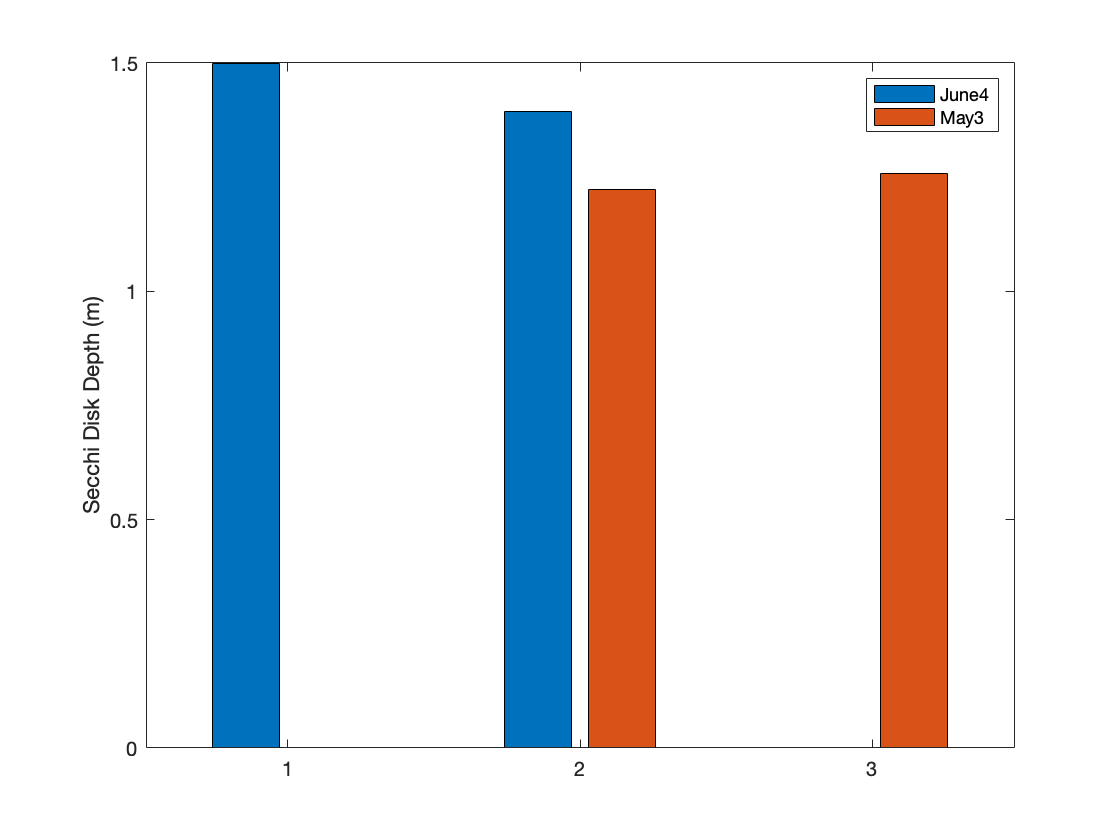


% Quick Visualization
secchi_demo = squeeze(nanmean(Secchi,1));

figure(3)
bar(secchi_demo)
ylabel('Secchi Disk Depth (m)')
legend({'June4', 'May3'})

## Apply Wei et al. (2018) SAVE Model 

for image = 1:size(L8coord.rrs_443,3)
    for site = 1:size(L8coord.rrs_443,2)
        for meas = 1:size(L8coord.rrs_443,1)
        
        % Set Rrs Values
        Rrs = [L8coord.rrs_443(meas,site,image) L8coord.rrs_482(meas,site,image) L8coord.rrs_561(meas,site,image) L8coord.rrs_655(meas,site,image)];
        Rrs(Rrs<0)=nan
        % Apply SAVE model
        [Rrs412(meas,:,site,image), aph(meas,:,site,image), adg(meas,:,site,image), ad(meas,:,site,image), ag(meas,:,site,image)] = save_model(Rrs, wl);
        
        end
    end
end

Rrs = 1×4
    0.0086    0.0122    0.0170    0.0094


Rrs = 1×4
    0.0096    0.0132    0.0172    0.0095


Rrs = 1×4
    0.0088    0.0125    0.0168    0.0092


Rrs = 1×4
    0.0069    0.0106    0.0163    0.0098


Rrs = 1×4
    0.0079    0.0117    0.0168    0.0095


Rrs = 1×4
    0.0091    0.0126    0.0169    0.0093


Rrs = 1×4
    0.0090    0.0126    0.0175    0.0103


Rrs = 1×4
    0.0082    0.0121    0.0170    0.0099


Rrs = 1×4
    0.0078    0.0118    0.0166    0.0095


Rrs = 1×4
    0.0093    0.0127    0.0174    0.0100


Rrs = 1×4
    0.0089    0.0124    0.0171    0.0100


Rrs = 1×4
    0.0091    0.0124    0.0172    0.0101


Rrs = 1×4
    0.0093    0.0127    0.0174    0.0102


Rrs = 1×4
    0.0091    0.0127    0.0173    0.0104


Rrs = 1×4
    0.0089    0.0124    0.0173    0.0104


Rrs = 1×4
    0.0087    0.0122    0.0170    0.0104


Rrs = 1×4
    0.0086    0.0123    0.0170    0.0103


Rrs = 1×4
    0.0086    0.0124    0.0171    0.0105


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
   NaN   NaN   NaN   NaN


Rrs = 1×4
    0.0047    0.0084    0.0144    0.0095


Rrs = 1×4
    0.0051    0.0089    0.0148    0.0099


Rrs = 1×4
    0.0050    0.0088    0.0146    0.0099


Rrs = 1×4
    0.0046    0.0082    0.0140    0.0096


Rrs = 1×4
    0.0050    0.0086    0.0146    0.0099


Rrs = 1×4
    0.0049    0.0088    0.0144    0.0100


Rrs = 1×4
    0.0045    0.0079    0.0138    0.0093


Rrs = 1×4
    0.0046    0.0084    0.0141    0.0097


Rrs = 1×4
    0.0042    0.0079    0.0141    0.0098


Rrs = 1×4
    0.0081    0.0117    0.0168    0.0108


Rrs = 1×4
    0.0084    0.0118    0.0170    0.0108


Rrs = 1×4
    0.0082    0.0117    0.0165    0.0110


Rrs = 1×4
    0.0070    0.0110    0.0161    0.0103


Rrs = 1×4
    0.0086    0.0121    0.0172    0.0109


Rrs = 1×4
    0.0084    0.0120    0.0170    0.0114


Rrs = 1×4
    0.0073    0.0109    0.0160    0.0104


Rrs = 1×4
    0.0091    0.0123    0.0174    0.0113


Rrs = 1×4
    0.0078    0.0114    0.0167    0.0106


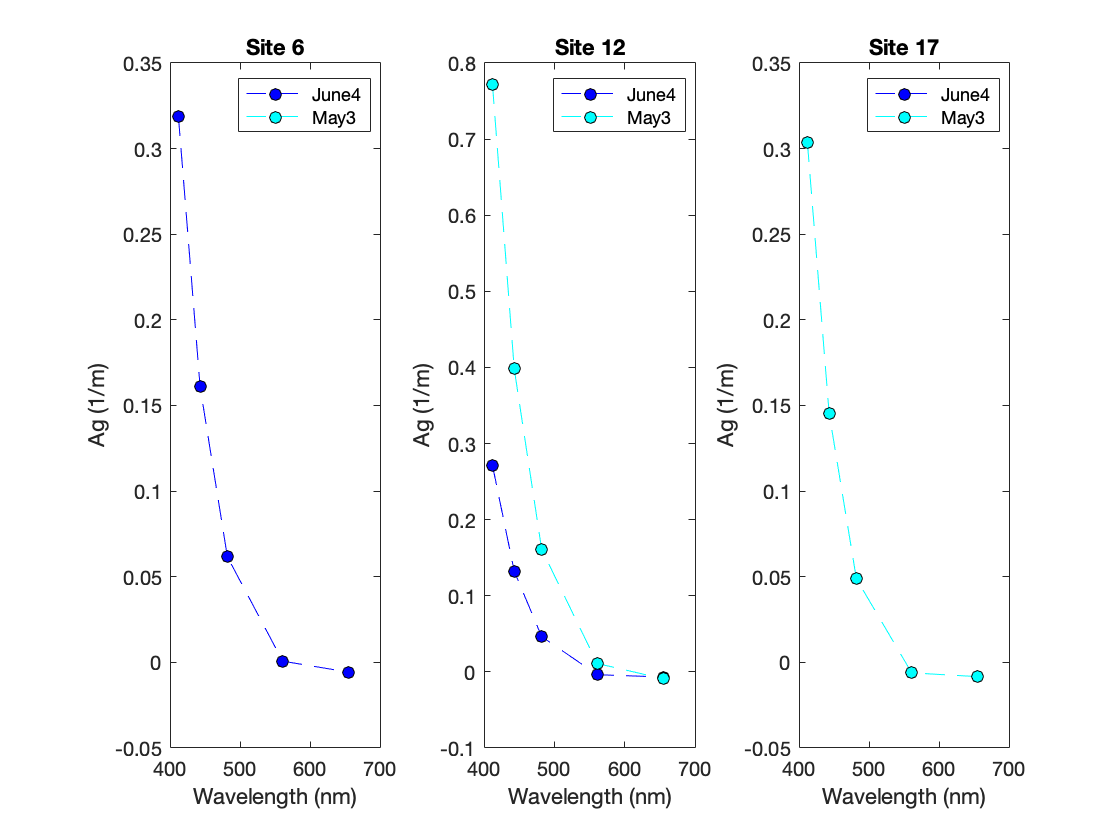


% Quick Visualization
wln = [412 wl];
ag_demo = squeeze(nanmean(ag,1));
ad_demo = squeeze(nanmean(ad,1));
adg_demo = squeeze(nanmean(adg,1));
aph_demo = squeeze(nanmean(aph,1));

figure(4)
for pl = 1:size(ag_demo,2)
    subplot(1,3,pl)
    for image = 1:size(ag_demo,3)
        plot(wln, ag_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Ag (1/m)')
        hold on
    end
    legend({'June4', 'May3'})
    title(site_names{pl})
end

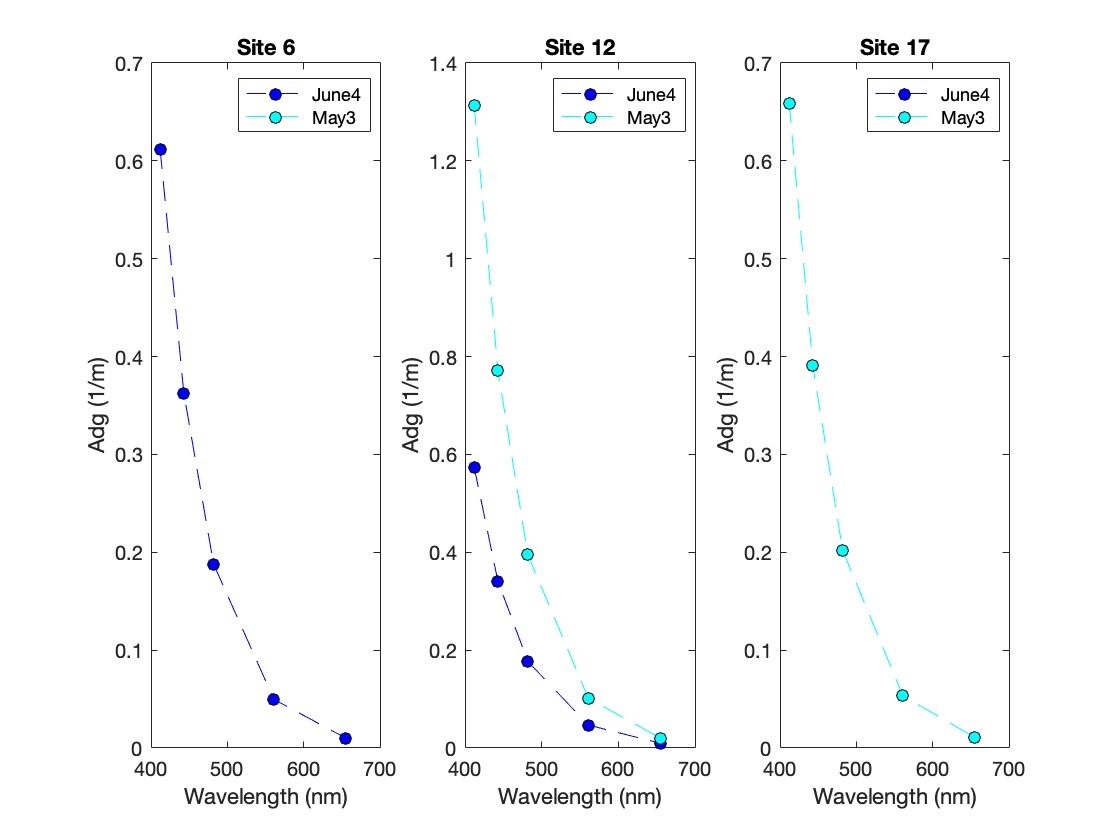

figure(5)
for pl = 1:size(ag_demo,2)
    subplot(1,3,pl)
    for image = 1:size(adg_demo,3)
        plot(wln, adg_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Adg (1/m)')
        hold on
    end
    legend({'June4', 'May3'})
    title(site_names{pl})
end

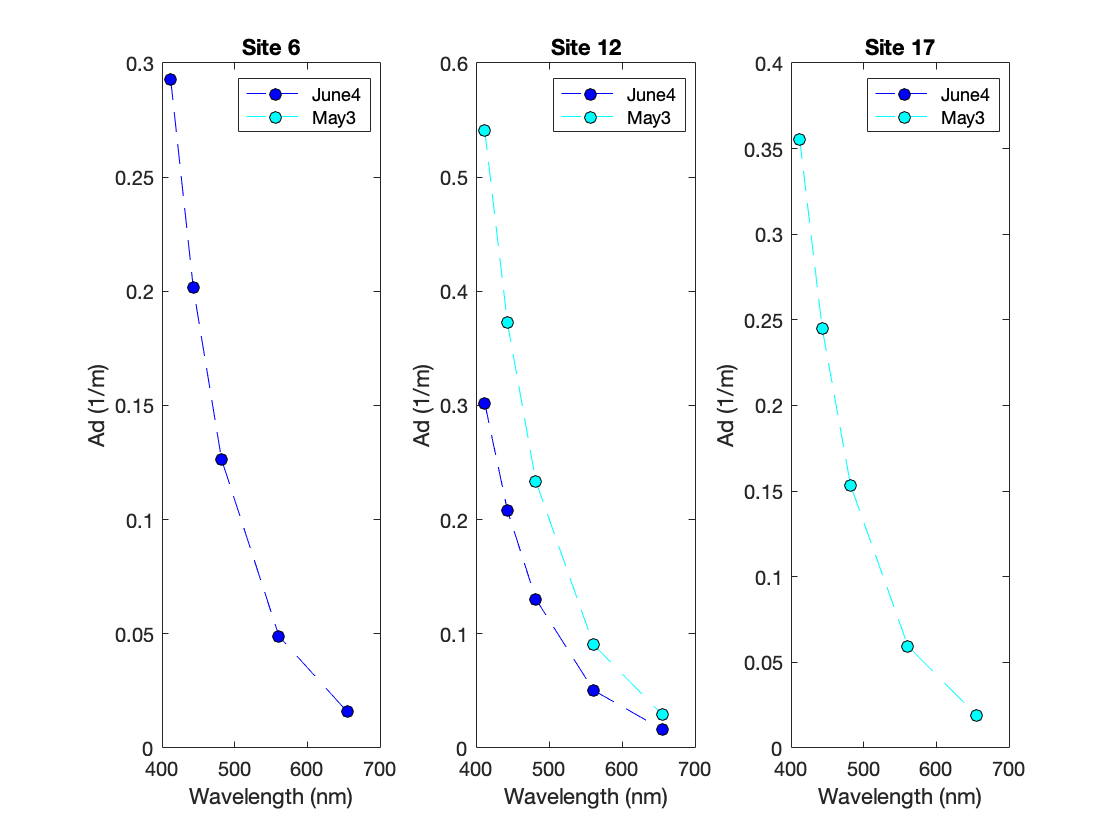

figure(6)
for pl = 1:size(ad_demo,2)
    subplot(1,3,pl)
    for image = 1:size(ad_demo,3)
        plot(wln, ad_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Ad (1/m)')
        hold on
    end
    legend({'June4', 'May3'})
    title(site_names{pl})
end

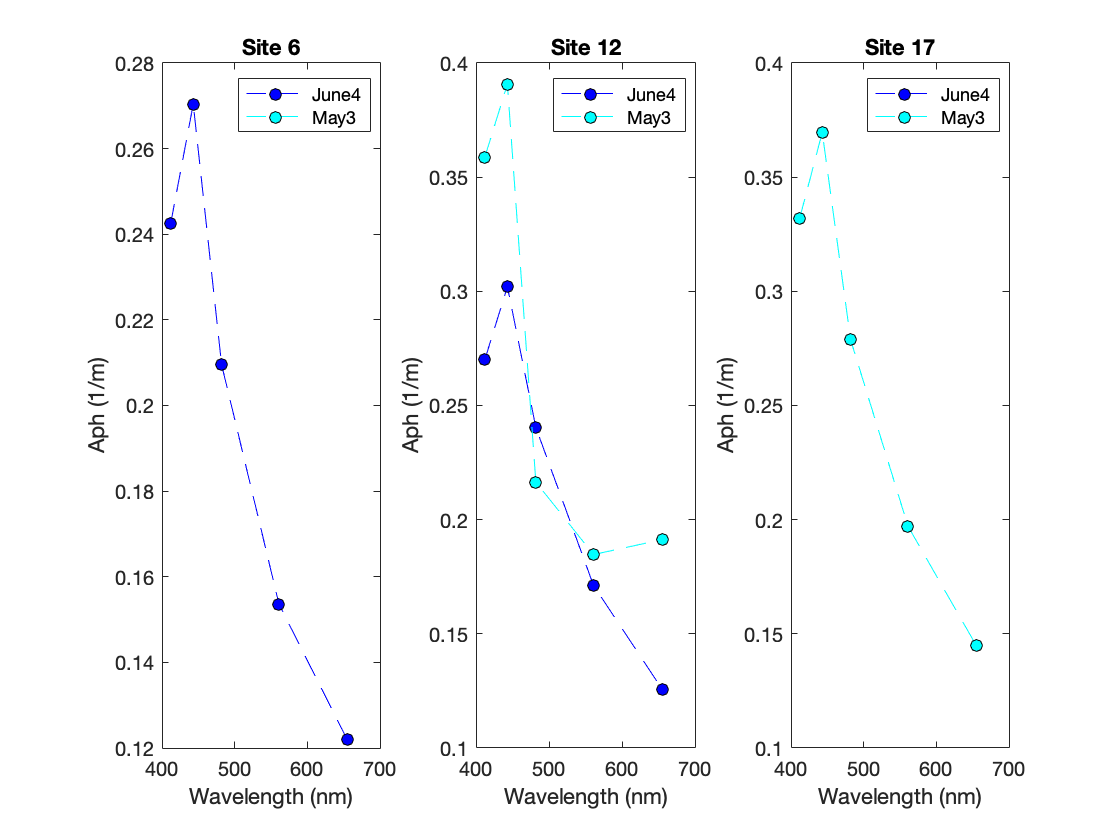

figure(7)
for pl = 1:size(aph_demo,2)
    subplot(1,3,pl)
    for image = 1:size(aph_demo,3)
        plot(wln, aph_demo(:,pl,image),'o--','color',colors(image,:), 'MarkerFaceColor',colors(image,:),'MarkerEdgeColor','k')
        xlabel('Wavelength (nm)')
        ylabel('Aph (1/m)')
        hold on
    end
    legend({'June4', 'May3'})
    title(site_names{pl})
end

chl_demo = squeeze(nanmean(L8coord.chl,1));
kd_490_demo = squeeze(nanmean(L8coord.kd_490,1));
rrs_443_demo=squeeze(nanmean(L8coord.rrs_443,1));
rrs_482_demo=squeeze(nanmean(L8coord.rrs_482,1));
rrs_561_demo=squeeze(nanmean(L8coord.rrs_561,1));
rrs_655_demo=squeeze(nanmean(L8coord.rrs_655,1));